# XTD_C5: Exemplar XTD Models (Representational Cycling)

% fileDirs = [{'D:\PFC\GE11_Session132'},...
%     {'D:\PFC\GE13_Session083'},...
%     {'D:\PFC\GE14_Session123'},...
%     {'D:\PFC\GE17_Session095'},...
%     {'D:\PFC\GE24_Session096'}];
fileDirs = [{'D:\WorkBigDataFiles\PFC\GE11_Session132'},...
    {'D:\WorkBigDataFiles\PFC\GE13_Session083'},...
    {'D:\WorkBigDataFiles\PFC\GE14_Session123'},...
    {'D:\WorkBigDataFiles\PFC\GE17_Session095'},...
    {'D:\WorkBigDataFiles\PFC\GE24_Session096'}];

rbDivMap = diverging_map(0:0.01:1,[0 0.4 0.8], [0.8 0 0.4]);
nanWmap = rbDivMap;
nanWmap(1,:) = [1,1,1];

## Compile Data Across Rats

prevTrlLat = cell(1,4);
trialLightLat = cell(1,4);
pokeInLat = cell(1,4);
rwdSigLat = cell(1,4);
pokeOutLat = cell(1,4);
rwdLat = cell(1,4);
nxtTrlLat = cell(1,4);
for ani = 1:length(fileDirs)
    aniDta = load([fileDirs{ani} '\xtd_mlb_wChance.mat'], 'modInt_PosDec_Real', 'modInt_PosDec_ChanceFull', 'modInt_PosDec_ChancePos',...
        'modPreDec_PosDec_Real', 'modPreDec_PosDec_ChanceFull', 'modPreDec_PosDec_ChancePos',...
        'modPstDec_PosDec_Real', 'modPstDec_PosDec_ChanceFull', 'modPstDec_PosDec_ChancePos');   
    %%%
    fns = fieldnames(aniDta);
    if ani == 1
        for fn = 1:length(fns)
            eval(sprintf('%s = aniDta.%s;', fns{fn}, fns{fn}));
        end
    else
        for d = 1:numel(modInt_PosDec_Real)
            for fn = 1:length(fns)
                eval(sprintf('%s{d} = cat(3,%s{d}, aniDta.%s{d});', fns{fn}, fns{fn}, fns{fn}));
            end
        end
    end
    load([fileDirs{ani} '\xtd_mlb_wChance.mat'], 'trialInfo', 'mlb');
    cur_TrialInfo = cell2mat(trialInfo(cellfun(@(a)~isempty(a),trialInfo))');
    for pos = 1:mlb.seqLength
        curPosLog = [cur_TrialInfo.Position]==pos;
        if strcmp(mlb.alignments{1}, 'PokeIn')
            prevTrlLat{pos} = [prevTrlLat{pos},([cur_TrialInfo(curPosLog).PrevTrlEnd] - [cur_TrialInfo(curPosLog).PokeInIndex])/mlb.sampleRate];
            trialLightLat{pos} = [trialLightLat{pos}, ([cur_TrialInfo(curPosLog).PortLightIndex] - [cur_TrialInfo(curPosLog).PokeInIndex])/mlb.sampleRate];
            pokeInLat{pos} = [pokeInLat{pos},([cur_TrialInfo(curPosLog).PokeInIndex] - [cur_TrialInfo(curPosLog).PokeInIndex])/mlb.sampleRate];
            rwdSigLat{pos} = [rwdSigLat{pos}, ([cur_TrialInfo(curPosLog).RewardSignalIndex] - [cur_TrialInfo(curPosLog).PokeInIndex])/mlb.sampleRate];
            pokeOutLat{pos} = [pokeOutLat{pos}, [cur_TrialInfo(curPosLog).PokeDuration]];
            rwdLat{pos} = [rwdLat{pos}, ([cur_TrialInfo(curPosLog).RewardIndex] - [cur_TrialInfo(curPosLog).PokeInIndex])/mlb.sampleRate];
            nxtTrlLat{pos} = [nxtTrlLat{pos}, ([cur_TrialInfo(curPosLog).NextTrlStart] - [cur_TrialInfo(curPosLog).PokeInIndex])/mlb.sampleRate];
        elseif strcmp(mlb.alignmnents{1}, 'PokeOut')
            prevTrlLat{pos} = [prevTrlLat{pos},([cur_TrialInfo(curPosLog).PrevTrlEnd] - [cur_TrialInfo(curPosLog).PokeOutIndex])/mlb.sampleRate];
            trialLightLat{pos} = [trialLightLat{pos}, ([cur_TrialInfo(curPosLog).PortLightIndex] - [cur_TrialInfo(curPosLog).PokeOutIndex])/mlb.sampleRate];
            pokeInLat{pos} = [pokeOutLat{pos}, [cur_TrialInfo(curPosLog).PokeDuration]*-1];
            rwdSigLat{pos} = [rwdSigLat{pos}, ([cur_TrialInfo(curPosLog).RewardSignalIndex] - [cur_TrialInfo(curPosLog).PokeOutIndex])/mlb.sampleRate];
            pokeOutLat{pos} = [pokeInLat{pos},([cur_TrialInfo(curPosLog).PokeOutIndex] - [cur_TrialInfo(curPosLog).PokeOutIndex])/mlb.sampleRate];
            rwdLat{pos} = [rwdLat{pos}, ([cur_TrialInfo(curPosLog).RewardIndex] - [cur_TrialInfo(curPosLog).PokeOutIndex])/mlb.sampleRate];
            nxtTrlLat{pos} = [nxtTrlLat{pos}, ([cur_TrialInfo(curPosLog).NextTrlStart] - [cur_TrialInfo(curPosLog).PokeOutIndex])/mlb.sampleRate];
        end
    end
end


## Plot Stuff

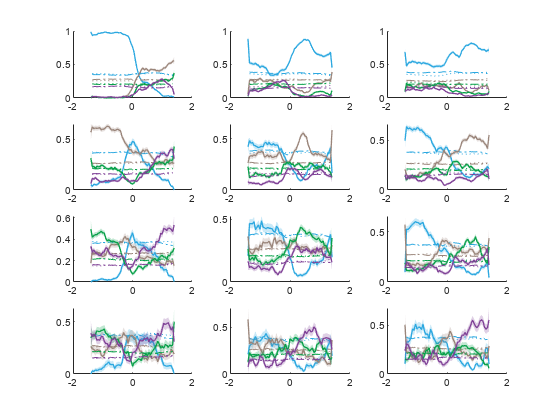

sps = reshape(1:(mlb.seqLength * 3), [3,mlb.seqLength])';
figure;
for pos = 1:mlb.seqLength
    for pos2 = 1:mlb.seqLength
        subplot(mlb.seqLength, 3, sps(pos,1));
        tempIntReal = modInt_PosDec_Real{pos,pos,pos}(:,pos2,:);
        tempIntChanceF = mean(modInt_PosDec_ChanceFull{pos,pos,pos}(:,pos2,:),3);
        tempIntChanceP = mean(modInt_PosDec_ChancePos{pos,pos,pos}(:,pos2,:),3);
        mlb.PlotMeanVarLine(mlb.obsvTimeVect, tempIntReal, 3, 0, mlb.PositionColors(pos2,:));
        plot(mlb.obsvTimeVect, tempIntChanceF, ':', 'color', mlb.PositionColors(pos2,:));
        plot(mlb.obsvTimeVect, tempIntChanceP, '-.', 'color', mlb.PositionColors(pos2,:));

        subplot(mlb.seqLength, 3, sps(pos,2));
        tempPreDecReal = modPreDec_PosDec_Real{pos,pos,pos}(:,pos2,:);
        tempPreDecChanceF = mean(modPreDec_PosDec_ChanceFull{pos,pos,pos}(:,pos2,:),3);
        tempPreDecChanceP = mean(modPreDec_PosDec_ChancePos{pos,pos,pos}(:,pos2,:),3);
        mlb.PlotMeanVarLine(mlb.obsvTimeVect, tempPreDecReal, 3, 0, mlb.PositionColors(pos2,:));
        plot(mlb.obsvTimeVect, tempPreDecChanceF, ':', 'color', mlb.PositionColors(pos2,:));
        plot(mlb.obsvTimeVect, tempPreDecChanceP, '-.', 'color', mlb.PositionColors(pos2,:));

        subplot(mlb.seqLength, 3, sps(pos,3));
        tempPstDecReal = modPstDec_PosDec_Real{pos,pos,pos}(:,pos2,:);
        tempPstDecChanceF = mean(modPstDec_PosDec_ChanceFull{pos,pos,pos}(:,pos2,:),3);
        tempPstDecChanceP = mean(modPstDec_PosDec_ChancePos{pos,pos,pos}(:,pos2,:),3);
        mlb.PlotMeanVarLine(mlb.obsvTimeVect, tempPstDecReal, 3, 0, mlb.PositionColors(pos2,:));
        plot(mlb.obsvTimeVect, tempPstDecChanceF, ':', 'color', mlb.PositionColors(pos2,:));
        plot(mlb.obsvTimeVect, tempPstDecChanceP, '-.', 'color', mlb.PositionColors(pos2,:));
    end
end

## Stats

## Repeated Measures ANOVAs

1) RM-ANOVAs for each exemplar model

- Trial Position x Decoded Position x Time x Model?

% RM-ANOVAs for well... everyfucking thing.
% Make a dang table of the rm-anova decoding observed vs chance distribution values
% Interval model RM-ANOVAs
% Pre-Decision RM-ANOVAs
% Post-Decision RM-ANOVAs


## Post-Hoc Obsv vs Chance

1) 

% Plot significance values so I can edit in Illustrator
% Paired t-tests with bonferroni/HDR corrections?
% One tailed t-tests against the mean chance with bonferroni/HDR corrections?
% Interval post-hocs
% Pre-Decision post-hocs
% Post-Decision post-hocs